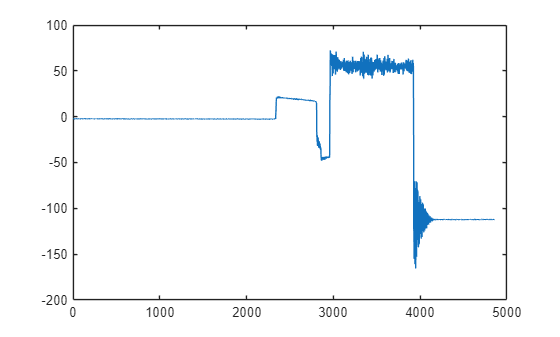

data = load("pomiary warte zapisania\all_engines_1350.mat");
tens_data = data.out.tens_cal;
column = 1;
plot(tens_data(:,column))

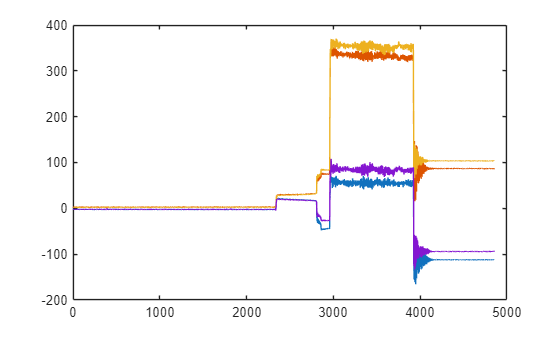

tens_data_cal = tens_data(:,column);
plot(tens_data)

t = 0:0.01:27.99;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

filter_tens = filter(b, a, tens_data_cal);
filter_all_tens = filter(b, a, tens_data); 

start_measure = 3000;
stop_measure = 3800;

avg = sum(mean(tens_data(start_measure:stop_measure, :)))/4

avg = 206.4948

% Separate calculation for each tensometer
vec_1 = [8.07, 24.86, 49.45, 83.06, 123.29, 171, 236.97, 303.99];
vec_2 = [7.17, 25.79, 53.38, 87.85, 127.16, 180.7, 271.88, 378.86];
vec_3 = [6.59, 23.86, 48.45, 86.52, 121.51, 170.11, 254.1, 290.92];
vec_4 = [6.72, 21.99, 51.15, 86.1, 128.08, 178.73, 220.11, 288.9];

vec = [vec_1; vec_2; vec_3; vec_4];
vec = vec * 9.81 / 1000

vec =     0.0792    0.2439    0.4851    0.8148    1.2095    1.6775    2.3247    2.9821
    0.0703    0.2530    0.5237    0.8618    1.2474    1.7727    2.6671    3.7166
    0.0646    0.2341    0.4753    0.8488    1.1920    1.6688    2.4927    2.8539
    0.0659    0.2157    0.5018    0.8446    1.2565    1.7533    2.1593    2.8341



colors = [
    0.10 0.25 0.50;   % ciemny niebieski
    0.65 0.25 0.05;   % ciemny pomarańczowy
    0.10 0.45 0.25;   % ciemny zielony
    0.40 0.15 0.45    % ciemny fioletowy
];

x_axis = [5, 10, 15, 20, 25, 30, 35, 40];
plt = plot(x_axis, vec, '.', 'MarkerSize', 18)

plt =   4×1 Line array:

  Line
  Line
  Line
  Line


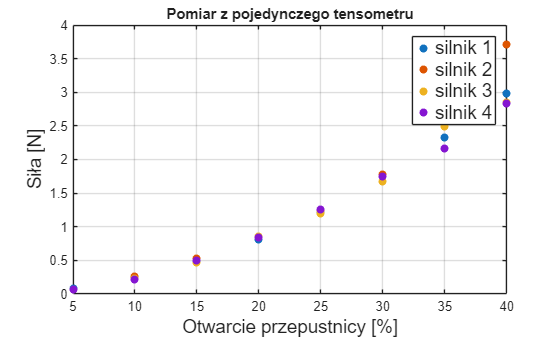

title("Pomiar z pojedynczego tensometru")
legend("silnik 1", "silnik 2", "silnik 3", "silnik 4", 'FontSize', 14)
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Otwarcie przepustnicy [%]", 'FontSize', 14)
grid on

% Sum of calculations
vec_1_sum = [5.92, 19.47, 52.18, 87.68, 131.84, 186.89, 286.05, 341.05];
vec_2_sum = [7.50, 24.54, 48.36, 89.74, 131.66, 178.46, 265.15, 350.55];
vec_3_sum = [8.15, 26.75, 52.34, 81.45, 135.84, 181.58, 277.45, 355.21];
vec_4_sum = [6.97, 26.18, 38.89, 84.49, 123.00, 176.16, 270.13, 331.30];

vec_sum = [vec_1_sum; vec_2_sum; vec_3_sum; vec_4_sum];
vec_sum = vec_sum * 9.81 / 1000

vec_sum =     0.0581    0.1910    0.5119    0.8601    1.2934    1.8334    2.8062    3.3457
    0.0736    0.2407    0.4744    0.8803    1.2916    1.7507    2.6011    3.4389
    0.0800    0.2624    0.5135    0.7990    1.3326    1.7813    2.7218    3.4846
    0.0684    0.2568    0.3815    0.8288    1.2066    1.7281    2.6500    3.2501



x_axis = [5, 10, 15, 20, 25, 30, 35, 40];
plt = plot(x_axis, vec_sum, '.', 'MarkerSize', 18)

plt =   4×1 Line array:

  Line
  Line
  Line
  Line


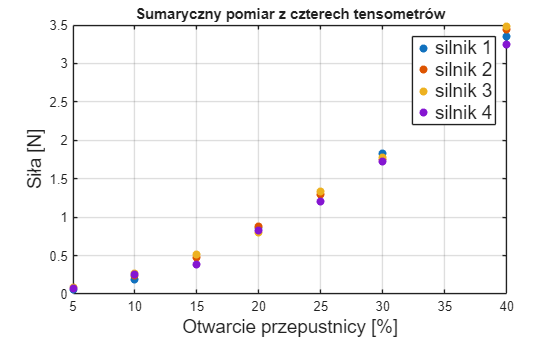

title("Sumaryczny pomiar z czterech tensometrów")
legend("silnik 1", "silnik 2", "silnik 3", "silnik 4", 'FontSize', 14)
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Otwarcie przepustnicy [%]", 'FontSize', 14)
grid on

% All engines at the same time
vec_all = [8.00, 27.13, 55.89, 93.75, 135.93, 186.91, 236.79, 292.76];
vec_all = vec_all * 9.81 / 1000;
x_axis = [0.05, 0.10, 0.15, 0.20, 0.25, 0.30, 0.35, 0.40];
avg_sum_single_eng = (vec_1_sum + vec_2_sum + vec_3_sum + vec_4_sum)/4;
avg_sum_single_eng = avg_sum_single_eng * 9.81 / 1000;

u = x_axis(:);
F = vec_all(:);

% Macierz modelu:
% F = a*u^2 + b*u + c
A = [u.^2, u, ones(size(u))];

% Ograniczenia dolne:
% a    b    c
lb = [-Inf, -Inf, -Inf];

% Brak ograniczeń górnych
ub = [Inf, Inf, Inf];

p = lsqlin(A, F, [], [], [], [], lb, ub);

a = p(1);
b = p(2);
c = p(3);

fprintf("a = %.8f\n", a);

a = 11.50199143


fprintf("b = %.8f\n", b);

b = 2.94505543


fprintf("c = %.8f\n", c);

c = -0.12407197


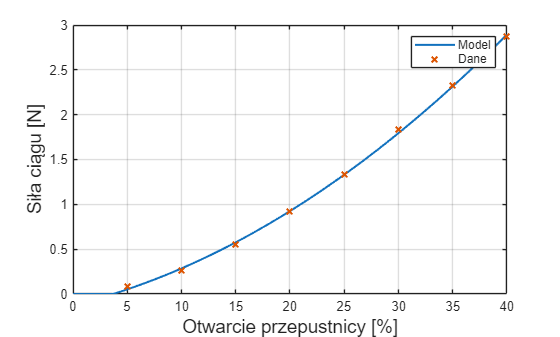


u_plot = linspace(0, 0.40, 200);
F_model = a*u_plot.^2 + b*u_plot + c;

F_model(F_model < 0)=0;

plot(u_plot*100, F_model, 'LineWidth', 1.5)
hold on
plot(x_axis*100, vec_all, 'x', 'LineWidth', 1.5)
grid on
xlabel("Otwarcie przepustnicy [%]", 'Fontsize', 14)
ylabel("Siła ciągu [N]", 'Fontsize', 14)
legend("Model", "Dane")

hold off;

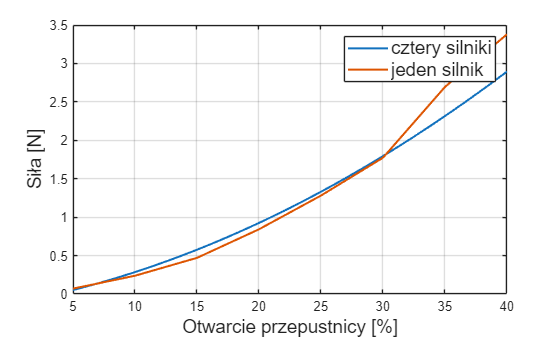

u_plot = linspace(0, 0.40, 200);
F_model = a*u_plot.^2 + b*u_plot + c;

F_model(F_model < 0)=0;

% plot(x_axis*100, vec_all, "LineWidth", 1.5)
plot(u_plot*100, F_model, "LineWidth", 1.5)
hold on
plot(x_axis*100, avg_sum_single_eng, "LineWidth", 1.5)
grid on
ylabel("Siła [N]", 'Fontsize', 14)
xlabel("Otwarcie przepustnicy [%]", 'Fontsize', 14)
legend("cztery silniki", "jeden silnik", 'FontSize', 14)
xlim([5 40])
hold off

data = load("Pomiary\dane_silniki\tens_3_silnik_2_1400.mat")

data = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


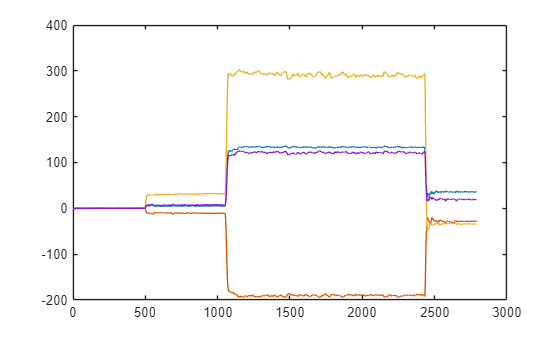

tens_data = data.out.tens_cal;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

filter_all_tens = filter(b, a, tens_data); 
plot(filter_all_tens)